# 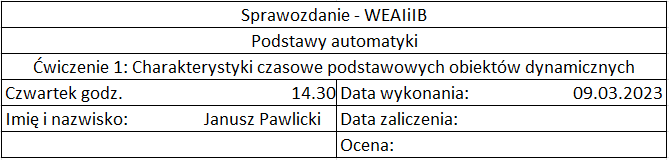

## 1 Wstęp

### 1.1 Cel Laboratorium

Zapoznanie się z charakterystykami czasowymi (odpowiedziami obiektu na określone wymuszenie w dziedzinie czasu). Ćwiczenie ma być wykonane drogą symulacji w środowisku MATLAB. W czasie ćwiczenia będą badane odpowiedzi obiektów na następujące typy wymuszeń:

- skok jednostkowy ( charakterystyki skokowe )

- delta Diraca ( charakterystyki impulsowe )

Należy zbadać odpowiedzi obiektów takich jak:

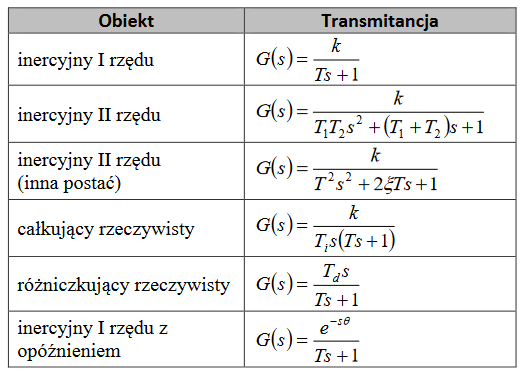

Dla obiektu (charakterystyka czsowa)

### 1.2 Transmitancja operatorowa

Transmitancja operatorowa (funkcja przejścia) to stosunek transformaty Laplace'a sygnału wyjściowego Y(s) do transformaty Laplace'a sygnału wejściowego U(s) przy zerowych warunkach początkowych:

Transmitancja w postaci wielomianowej jest dana wzorem:

W Matlabie transmitancja jest reprezentowana przez dwa wektory, zawierające współczynniki jej licznika i mianownika (w kolejności od najwyższej potęgi „s”). Sposób zapisu powyższych obiektów jest podany w tabeli:

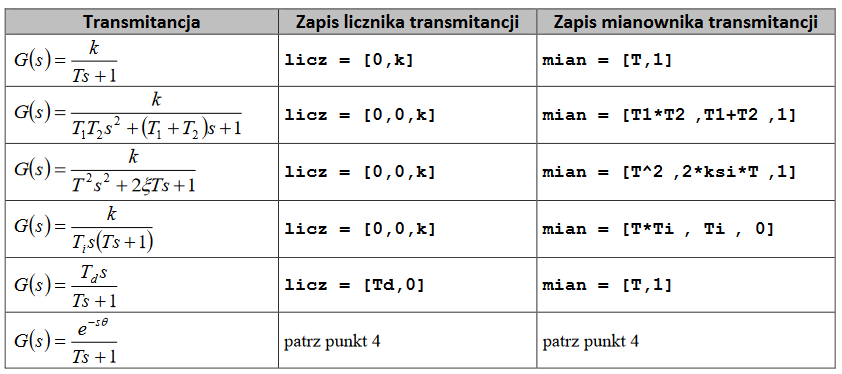

### 1.3 Obiekt inercyjny I rzędu z opóźnieniem

W systemach dynamicznych często możemy się spotkać z pojęciem czasu opóźnienia. Przykładem może być zjawisko przepływu cieczy przez rurociąg. Zakładamy, że przepływ jest tłokowy i czas przepływu pojedynczej cząstki cieczy wzdłuż całego rurociągu równy jest theta. W tym przypadku odcinek rurociągu można traktować jako element opóźniający

Jeżeli przyjmiemy, że zachowanie się pewnej zmiennej u wlotu do rurociągu określa funkcja f(t) (reprezentująca np. temperaturę lub skład cieczy) to po czasie theta na końcu rurociągu zaobserwujemy identyczny przebieg tej zmiennej.

Transformata Laplace’a funkcji przesuniętej w czasie o theta jednostek czasu wynosi:

Wynika stąd, że zależność zmiennej wyjściowej od zmiennej wejściowej dla układu opóźniającego

wyraża się transmitancją **e^-s * theta.**

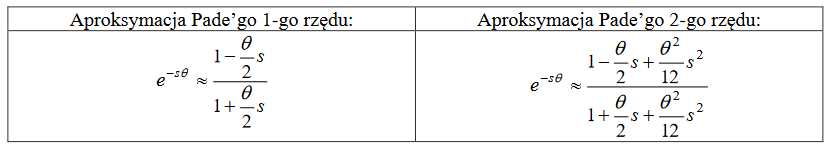

Aproksymacja Pade’go jest zaimplementowana w Matlabie w funkcji `pade`. W celu zamodelowania obiektu inercyjnego I rzędu z opóźnieniem w Matlabie należy wykonać poniższe czynności:

a) Wyznaczamy transmitancję członu opóźniającego przy pomocy funkcji PADE:

`[licz_op,` `mian_op]` `=` `pad``e(theta,` `n)`

gdzie: theta – opóźnienie w [s], n – rząd aproksymacji (np. n = 5). Po wykonaniu tej instrukcji

otrzymujemy licznik i mianownik transmitancji członu opóźniającego zapisany pod zmiennymi

licz_op i mian_op.

b) Zapisujemy transmitancję obiektu inercyjnego bez opóźnienia:

`licz_iner` `=` `[0,k];` `mian_iner` `=` `[T,1];`

c) Łączymy obie transmitancje szeregowo za pomocą instrukcji SERIES:

`[licz,` `mian]` `=` `series(licz_op,` `mian_op,` `licz_iner,` `mian_iner);`

Otrzymujemy w ten sposób licznik i mianownik transmitancji obiektu inercyjnego z opóźnieniem.

## 2 Przebieg laboratorium

### Charaktrystyka czasowa dla podanych obiektów z wymuszeniem:

### A) Inercyjny I rzędu

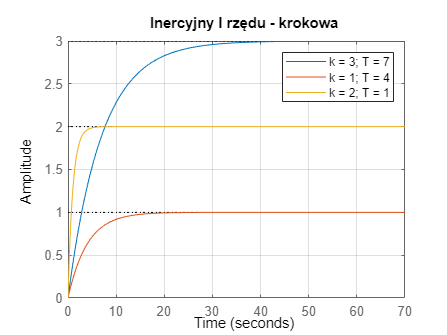

k = 3;
T = 7;
k1 = 1;
T1 = 4;
k2 = 2;
T2 = 1;


licz = [0, k];
mian = [T, 1];
licz1 = [0, k1];
mian1 = [T1, 1];
licz2 = [0, k2];
mian2 = [T2, 1];

step(licz, mian) % charakterystyka skokowa
hold on 
step(licz1, mian1)
step(licz2, mian2)
title('Inercyjny I rzędu - krokowa')
legend('k = 3; T = 7', 'k = 1; T = 4', 'k = 2; T = 1')
grid on;
hold off

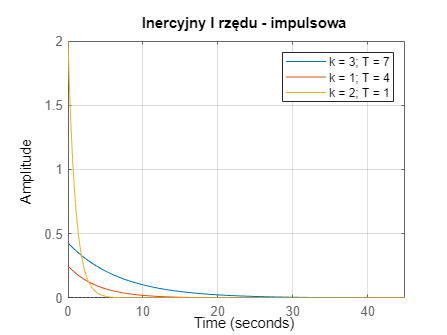


impulse(licz, mian) % charakterystyka impulsowa
hold on
impulse(licz1, mian1)
impulse(licz2, mian2)
title('Inercyjny I rzędu - impulsowa')
legend('k = 3; T = 7', 'k = 1; T = 4', 'k = 2; T = 1')
grid on;
hold off

### B) Inercyjny II rzędu

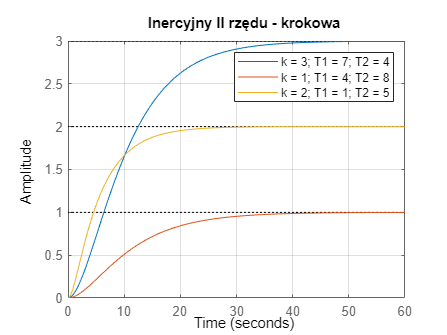

clear
k = 3;
T1 = 7;
T2 = 4;


k1 = 1;
T11 = 4;
T21 = 8;

k2 = 2;
T111 = 1;
T211 = 5;

licz = [0, 0, k];
mian = [T1 * T2, T1 + T2, 1];
licz1 = [0, 0, k1];
mian1 = [T11 * T21, T11 + T21, 1];
licz2 = [0, 0, k2];
mian2 = [T111 * T211, T111 + T211, 1];

step(licz, mian)
hold on 
step(licz1, mian1)
step(licz2, mian2)
title('Inercyjny II rzędu - krokowa')
legend('k = 3; T1 = 7; T2 = 4', 'k = 1; T1 = 4; T2 = 8', 'k = 2; T1 = 1; T2 = 5')
grid on;
hold off

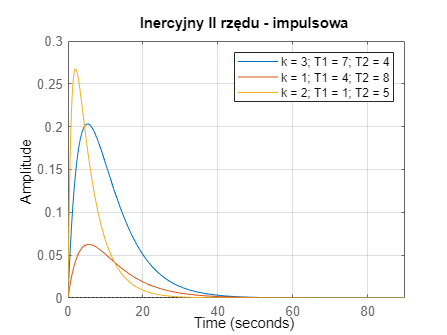


impulse(licz, mian)
hold on
impulse(licz1, mian1)
impulse(licz2, mian2)
title('Inercyjny II rzędu - impulsowa')
legend('k = 3; T1 = 7; T2 = 4', 'k = 1; T1 = 4; T2 = 8', 'k = 2; T1 = 1; T2 = 5')
grid on;
hold off

### C) Inercyjny II rzędu (inna postać)

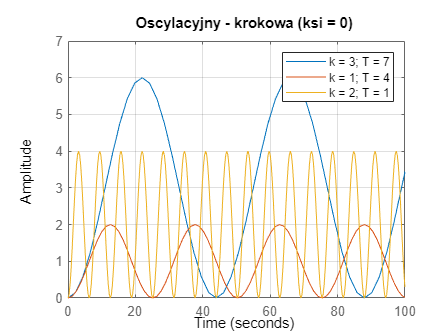

clear

k = 3;
T = 7;
k1 = 1;
T1 = 4;
k2 = 2;
T2 = 1;
ksi0 = 0;
ksi1 = 0.7;
ksi2 = 1;
ksi3 = 1.3;


%Układ oscylacyjny nietłumiony

licz = [0, 0, k];
mian = [T^2 ,2*ksi0*T ,1];
licz1 = [0, 0, k1];
mian1 = [T1^2 ,2*ksi0*T1 ,1];
licz2 = [0, 0, k2];
mian2 = [T2^2 ,2*ksi0*T2 ,1];

step(licz, mian)
hold on 
step(licz1, mian1)
step(licz2, mian2)
legend('k = 3; T = 7', 'k = 1; T = 4', 'k = 2; T = 1')
grid on;
axis([0 100 0 7])
title('Oscylacyjny - krokowa (ksi = 0)')
hold off

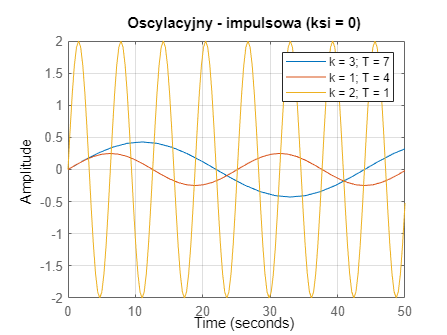


impulse(licz, mian)
hold on
impulse(licz1, mian1)
impulse(licz2, mian2)
legend('k = 3; T = 7', 'k = 1; T = 4', 'k = 2; T = 1')
grid on;
axis([0 50 -2 2])
title('Oscylacyjny - impulsowa (ksi = 0)')
hold off

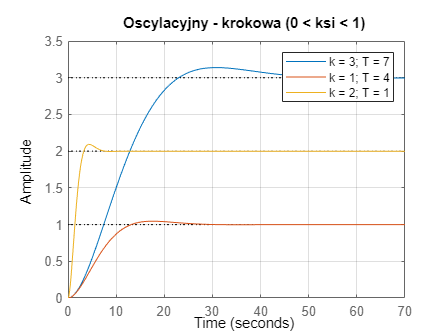


% Układ oscylacyjny tłumiony

licz3 = [0, 0, k];
mian3 = [T^2 ,2*ksi1*T ,1];
licz4 = [0, 0, k1];
mian4 = [T1^2 ,2*ksi1*T1 ,1];
licz5 = [0, 0, k2];
mian5 = [T2^2 ,2*ksi1*T2 ,1];

step(licz3, mian3)
hold on 
step(licz4, mian4) 
step(licz5, mian5)
legend('k = 3; T = 7', 'k = 1; T = 4', 'k = 2; T = 1')
grid on;
title('Oscylacyjny - krokowa (0 < ksi < 1)')
hold off

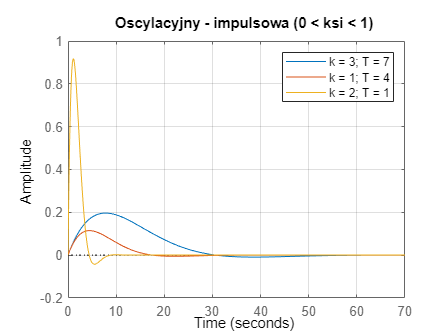


impulse(licz3, mian3)
hold on
impulse(licz4, mian4)
impulse(licz5, mian5)
legend('k = 3; T = 7', 'k = 1; T = 4', 'k = 2; T = 1')
grid on;
title('Oscylacyjny - impulsowa (0 < ksi < 1)')
hold off

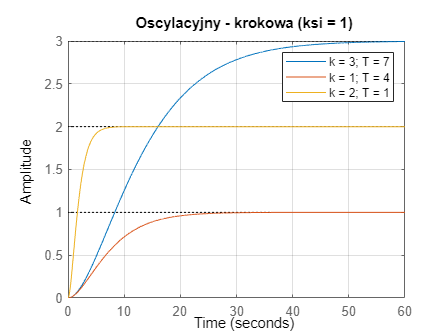


 % Układ aperiodyczny krytyczny 

licz6 = [0, 0, k];
mian6 = [T^2 ,2*ksi2*T ,1];
licz7 = [0, 0, k1];
mian7 = [T1^2 ,2*ksi2*T1 ,1];
licz8 = [0, 0, k2];
mian8 = [T2^2 ,2*ksi2*T2 ,1];

step(licz6, mian6)
hold on 
step(licz7, mian7) 
step(licz8, mian8)
legend('k = 3; T = 7', 'k = 1; T = 4', 'k = 2; T = 1')
grid on;
title('Oscylacyjny - krokowa (ksi = 1)')
hold off

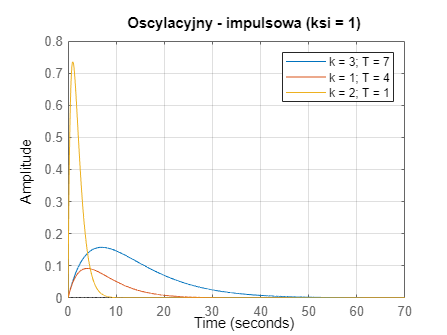


impulse(licz6, mian6)
hold on
impulse(licz7, mian7)
impulse(licz8, mian8)
legend('k = 3; T = 7', 'k = 1; T = 4', 'k = 2; T = 1')
grid on;
title('Oscylacyjny - impulsowa (ksi = 1)')
hold off

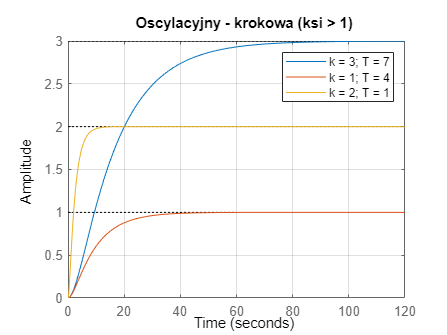


% Układ aperiodyczny

licz9 = [0, 0, k];
mian9 = [T^2 ,2*ksi3*T ,1];
licz10 = [0, 0, k1];
mian10= [T1^2 ,2*ksi3*T1 ,1];
licz11 = [0, 0, k2];
mian11= [T2^2 ,2*ksi3*T2 ,1];

step(licz9, mian9)
hold on 
step(licz10, mian10)
step(licz11, mian11)
legend('k = 3; T = 7', 'k = 1; T = 4', 'k = 2; T = 1')
grid on;
title('Oscylacyjny - krokowa (ksi > 1)')
hold off

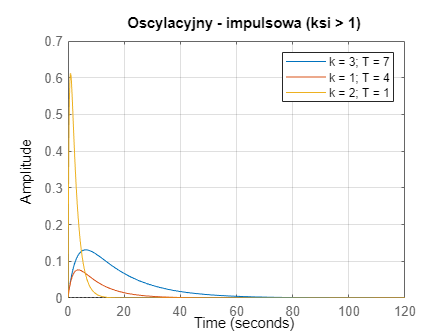


impulse(licz9, mian9)
hold on
impulse(licz10, mian10)
impulse(licz11, mian11)
legend('k = 3; T = 7', 'k = 1; T = 4', 'k = 2; T = 1')
grid on;
title('Oscylacyjny - impulsowa (ksi > 1)')
hold off

### D) Całkujący rzeczywisty

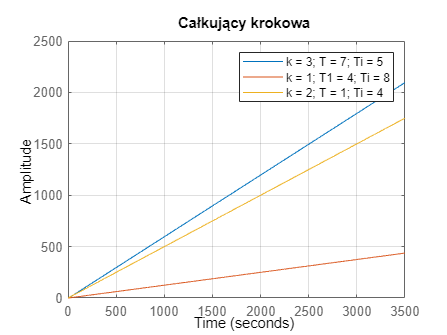

k = 3;
T = 7;
Ti = 5;
k1 = 1;
T1 = 4;
Ti1 = 8;
k2 = 2;
T2 = 1;
Ti2 = 4;

licz = [0, 0, k];
mian = [T * Ti, Ti, 0];
licz1 = [0, 0, k1];
mian1 = [T1 * Ti1, Ti1, 0];
licz2 = [0, 0, k2];
mian2 = [T2 * Ti2, Ti2, 0];

step(licz, mian)
hold on 
step(licz1, mian1) 
step(licz2, mian2)
title('Całkujący krokowa')
legend('k = 3; T = 7; Ti = 5', 'k = 1; T1 = 4; Ti = 8', 'k = 2; T = 1; Ti = 4')
grid on;
hold off

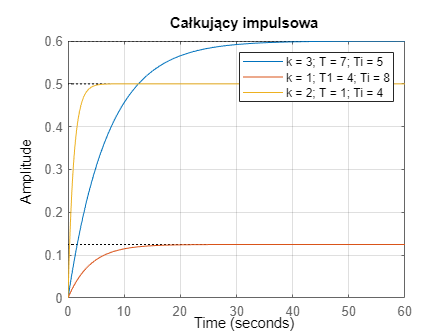


impulse(licz, mian)
hold on
impulse(licz1, mian1)
impulse(licz2, mian2)
title('Całkujący impulsowa')
legend('k = 3; T = 7; Ti = 5', 'k = 1; T1 = 4; Ti = 8', 'k = 2; T = 1; Ti = 4')
grid on;
hold off

### E) Różniczkujący rzeczywisty

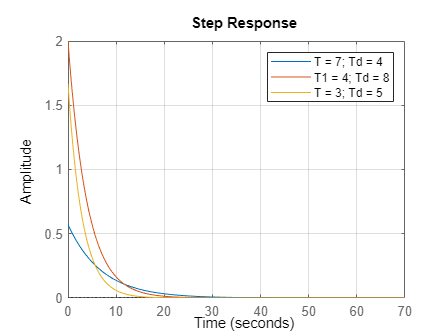

T = 7;
Td = 4;
T1 = 4;
Td1 = 8;
T2 = 3;
Td2 = 5;

licz = [Td, 0];
mian = [T, 1];
licz1 = [Td1, 0];
mian1 = [T1, 1];
licz2 = [Td2, 0];
mian2 = [T2, 1];

step(licz, mian)
hold on 
step(licz1, mian1) 
step(licz2, mian2)
legend('T = 7; Td = 4', 'T1 = 4; Td = 8', 'T = 3; Td = 5')
grid on;
hold off

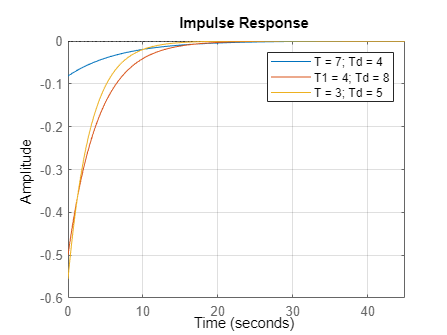


impulse(licz, mian)
hold on
impulse(licz1, mian1)
impulse(licz2, mian2)
legend('T = 7; Td = 4', 'T1 = 4; Td = 8', 'T = 3; Td = 5')
grid on;
hold off

### F) Inercyjny I rzędu z opóźnieniem

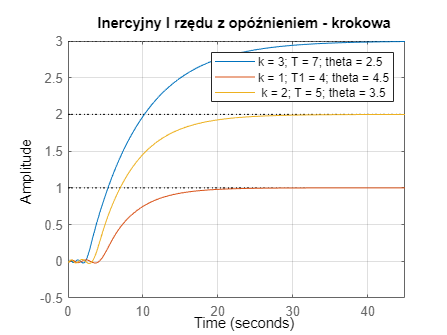

n = 5;

k = 3;
T = 7;
theta = 2.5;
k1 = 1;
T1 = 4;
theta1 = 4.5;
k2 = 2;
T2 = 5;
theta2 = 3.5;

[licz_op, mian_op] = pade(theta, n);
[licz_op1, mian_op1] = pade(theta1, n);
[licz_op2, mian_op2] = pade(theta2, n);

licz_iner = [0,k];
mian_iner = [T,1];
licz_iner1 = [0,k1];
mian_iner1 = [T1,1];
licz_iner2 = [0,k2];
mian_iner2 = [T2,1];

[licz, mian] = series(licz_op, mian_op, licz_iner, mian_iner);
[licz1, mian1] = series(licz_op1, mian_op1, licz_iner1, mian_iner1);
[licz2, mian2] = series(licz_op2, mian_op2, licz_iner2, mian_iner2);

step(licz, mian)
hold on 
step(licz1, mian1)
step(licz2, mian2)
legend('k = 3; T = 7; theta = 2.5', 'k = 1; T1 = 4; theta = 4.5',' k = 2; T = 5; theta = 3.5')
grid on;
title('Inercyjny I rzędu z opóźnieniem - krokowa')
hold off

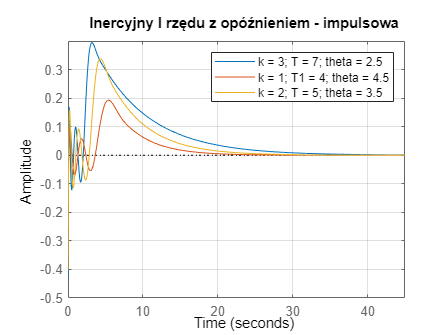


impulse(licz, mian)
hold on
impulse(licz1, mian1)
impulse(licz2, mian2)
legend('k = 3; T = 7; theta = 2.5', 'k = 1; T1 = 4; theta = 4.5','k = 2; T = 5; theta = 3.5')
grid on;
title('Inercyjny I rzędu z opóźnieniem - impulsowa')
hold off

## 3. Wnioski

Ćwiczenie nie sprawiło mi trudności. Było przyjemnym przypomnieniem wiadomości z poprzedniego smestru. Męczącą częścią ćwiczenia było przypisywanie zmiennych i ciągłe pisanie zmiennych licz i mian potrzebnych do stworzenia wykresów. Najdłużej zajęła mi część z układem inercyjnym II rzędu z opóźnieniem, ponieważ było w nim najwięcej przypadków. Wynikało to z rodzaji układu w zależności od ksi: (ksi = 0 - układ nietłumiony, 0 < ksi < 1 - układ tłumiony, ksi = 1 - układ aperiodyczny krytyczny, ksi > 1 - układ aperiodyczny).